## Data

% data
g0 = 9.81; % m/s^2
dia = 0.04; % m
mass = 0.0027;
DragC = 0.5;
LiftC = 0.5;
rho = 1.293; % kg/m^3

## Curve Simulation

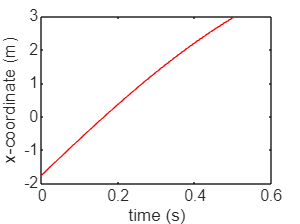

% Initial Conditions
x0 = -1.75;
y0 = 0;
z0 = 0.4;
Vx0 = 11;
Vy0 = 0;
Vz0 = 0;

q0 = [x0;y0;z0;Vx0;Vy0;Vz0];

% Simulation
[t1,q] = ode45(@SphereMotion1,[0 0.5],q0);

x1 = q(:,1);
y1 = q(:,2);
z1 = q(:,3);
Vx1 = q(:,4);
Vy1 = q(:,5);
Vz1 = q(:,6);

% plot different directions vs time
plot(t1,x1,'r')
xlabel('time (s)')
ylabel('x-coordinate (m)')

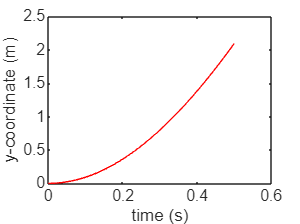


plot(t1,y1,'r')
xlabel('time (s)')
ylabel('y-coordinate (m)')

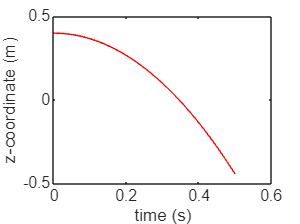


plot(t1,z1,'r')
xlabel('time (s)')
ylabel('z-coordinate (m)')

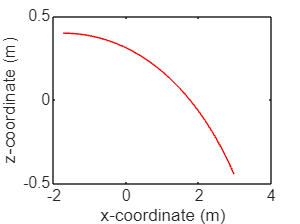


plot(x1, z1, 'r')
xlabel('x-coordinate (m)')
ylabel('z-coordinate (m)')

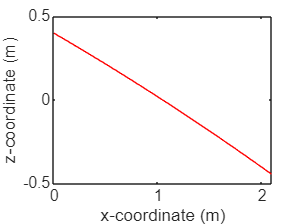


plot(y1, z1, 'r')
xlabel('x-coordinate (m)')
ylabel('z-coordinate (m)')

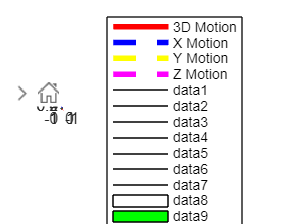


% stop the line when it hits the table
zmask = z1 >= 0.05;
x1(~zmask) = NaN;
y1(~zmask) = NaN;
z1(~zmask) = NaN;

%plot the trajectory and projections onto planes
plot3(x1,y1,z1,'r','Linewidth',3)
hold on
plot3(x1,y1*0,(z1*0+.4),'b--','Linewidth',3)
plot3((x1*0-1.75),y1,(z1*0+.4),'y--','Linewidth',3)
plot3((x1*0-1.75),y1*0,z1,'m--','Linewidth',3)
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
zlabel('z-coordinate (m)')
legend('3D Motion','X Motion','Y Motion','Z Motion')
box on
grid minor

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Visualization of ping pong table

xbox1 = [1.75 1.75 -1.75 -1.75 1.75];
ybox1 = [1.25 -1.25 -1.25 1.25 1.25];
zbox1 = [0.05 0.05 0.05 0.05 0.05];
xbox2 = [1.75 1.75 1.75 1.75 1.75];
ybox2 = [1.25 1.25 -1.25 -1.25 1.25];
zbox2 = [0.05 -0.05 -0.05 0.05 0.05];
xbox3 = [1.75 1.75 -1.75 -1.75 1.75];
ybox3 = [1.25 1.25 1.25 1.25 1.25];
zbox3 = [0.05 -0.05 -0.05 0.05 0.05];
xbox4 = [0 0 0 0 0];
ybox4 = [1.25 1.25 -1.25 -1.25 1.25];
zbox4 = [0.05 0.2 0.2 0.05 0.05];

plot3(xbox1, ybox1, zbox1, 'k')
plot3(xbox1, ybox1, -zbox1, 'k')
plot3(xbox2, ybox2, zbox2, 'k')
plot3(-xbox2, ybox2, zbox2, 'k')
plot3(xbox3, ybox3, zbox3,'k')
plot3(xbox3, -ybox3, zbox3,'k')
plot3(xbox4, ybox4, zbox4, 'k')

fill3(xbox1, ybox1, zbox1, 'w')
fill3(xbox1, ybox1, -zbox1, 'g')
fill3(xbox2, ybox2, zbox2, 'g')
fill3(-xbox2, ybox2, zbox2, 'g')
fill3(xbox3, ybox3, zbox3,'g')
fill3(xbox3, -ybox3, zbox3,'g')
fill3(xbox4, ybox4, zbox4, 'w')

%ybox5 = [-0.02 -0.02 0.02 0.02 -0.02];
%xbox5 = [-1.75 1.75 1.75 -1.75 -1.75]
%zbox5 = [0.055 0.055 0.055 0.055 0.055];
%fill3(xbox5, ybox5, zbox5, 'w')

xbox5 = [1.71 1.71 -1.71 -1.71 1.71];
ybox5 = [1.21 0.02 0.02 1.21 1.21];
zbox5 = [0.05 0.05 0.05 0.05 0.05];
fill3(xbox5, ybox5, zbox5, 'g')

xbox6 = [1.71 1.71 -1.71 -1.71 1.71];
ybox6 = [-0.02 -1.21 -1.21 -0.02 -0.02];
zbox6 = [0.05 0.05 0.05 0.05 0.05];
fill3(xbox6, ybox6, zbox6, 'g')

axis equal